# Segundo ejemplo del semestre

## Cálculo de $\pi$ utilizando Montecarlo

n = 10000;

x = rand([1 n]);
y = rand([1 n]);
r2 = x.^2 + y.^2;
    
inside = r2 <= 1;
outside = r2 > 1;
    
p = sum(inside)/n;
4*p

ans = 3.1596

    
q = 1 - p;
sd = sqrt(p*q);
alfa = 0.05;
z = norminv(1 - alfa/2);
se = sd/sqrt(n);

fprintf('%7.4f +/- %6.4f',4*p, 4*z*se)

 3.1596 +/- 0.0319

## Repetición del experimento anterior

Al repetir el experimento $m$ veces, podemos producir un histograma que nos muestre la distribución del experimento, como podemos ver, al ser un experimento de Bernoulli, se nos forma una curva normal, la cual nos muestra la media en 3.141, lo cual se asimila a $\pi$.

Utilizamos el comando `parfor`, que utiliza paralización para hacer el experimento más rápido, a través de los comandos `tic y toc `podemos medir que tan rápido es esto.

m = 10000;
val = zeros(1, m);

tic
for i = 1:m
    x = rand([1 n]);
    y = rand([1 n]);
    r2 = x.^2 + y.^2;
    
    inside = r2 <= 1;
    outside = r2 > 1;
    
    p = sum(inside)/n;
    val(i) = 4*p;
end
toc

Elapsed time is 0.818704 seconds.


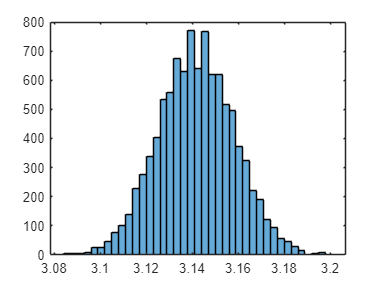


tic
parfor i = 1:m
    x = rand([1 n]);
    y = rand([1 n]);
    r2 = x.^2 + y.^2;
    
    inside = r2 <= 1;
    outside = r2 > 1;
    
    p = sum(inside)/n;
    val(i) = 4*p;
end
toc
histogram(val)

mean(val)

ans = 3.1417